clear;
if exist('DataSet','dir')
   rmdir('.\DataSet\', 's');
end

mkdir('.\DataSet\');

% 配置
global run_type;
run_type = 'io';
config;

L_recTre = 129.0309


% 产生信号
source;
tag;
global y_sig;
y_sig = y_source;

% % dB 单位信噪比
% y_noise = awgn(y_sig, 50);
% y_sig = y_noise;

global Length;
global Width;

## 房间内的随机点(测试集)

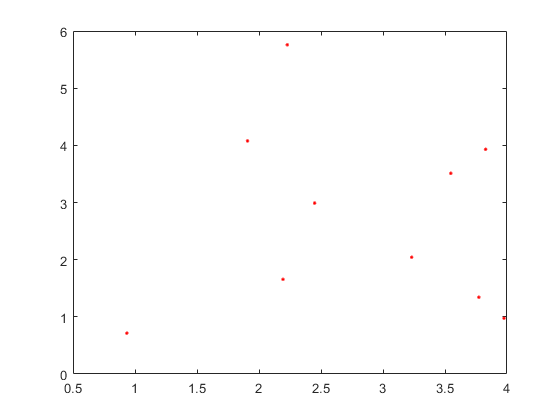

N_inside = 10;
x = Width * rand(1, N_inside);
y = Length * rand(1, N_inside);
figure; plot(x,y,'r.');


% 计算三个距离
for j=1:2
    [d1, d2, d3] = xy2d(x, y,j);
    single_run(d1, d2, d3, false, 'inside', j);
end

L_tag is
  103.6400  102.5602  108.0998  109.0176   99.5665  104.3064  103.6513  106.5440  107.2866  108.2731

delta t is
   1.0e-07 *

    0.0629    0.0475    0.1328    0.1558    0.0360    0.0652    0.0869    0.1043    0.1162    0.1393



Rate_miss = 0

L_tag is
  103.6686  102.6473  108.1353  109.0342   99.5901  104.3506  103.7740  106.5700  107.3224  108.2921

delta t is
   1.0e-07 *

    0.0634    0.0485    0.1334    0.1562    0.0365    0.0659    0.0880    0.1048    0.1168    0.1398



Rate_miss = 0

## 房间周围的随机点

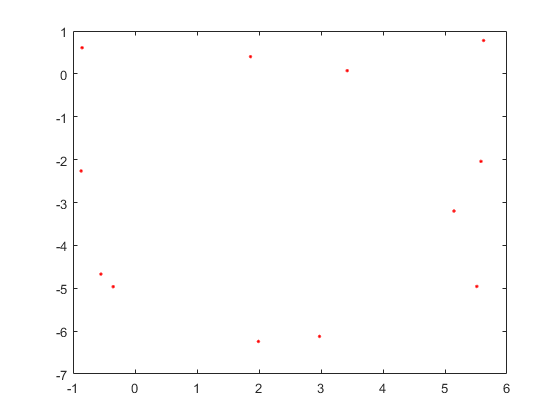

% 1/4 的数量
N_outside = 3;
x0 = rand(4, N_outside);
y0 = rand(4, N_outside);

x0 = [((Width / 2 + 1) * x0(:, 1:floor(N_outside / 2)))   (Width / 2 + x0(:, round(N_outside / 2) : end))];
y0 = [(Length / 2 + y0(:, 1:floor(N_outside / 2)))  ((Length / 2 + 1) * y0(:, round(N_outside / 2): end))];

x0(1,:) = -1 * x0(1, :);
x0(3,:) = -1 * x0(3, :);
y0(3,:) = -1 * y0(3, :);
y0(4,:) = -1 * y0(4, :);

% 坐标原点
x0 = x0 - (-1) * (Width / 2) * ones(size(x0));
y0 = y0 - 1 * (Length / 2) * ones(size(y0));

% 画出散点
figure; plot(x0,y0,'r.');


% 计算三个距离
for j=1:2
    [d1_0, d2_0, d3_0] = xy2d2(x0, y0, j);
    SinglePoint2(x0, y0, d1_0, d2_0, d3_0, false, 'outside', j);
end

  156.4720  120.7533  120.9808
  147.3063  225.5638  174.6438
  151.5611  118.1460  116.8536
  149.7308  211.8948  224.9298

delta t is
   1.0e-07 *

    0.0977    0.0193    0.0761
    0.1534    0.2299    0.2865
    0.0917    0.0144    0.0133
    0.1312    0.2012    0.2374

  156.5029  120.7986  120.9963
  147.3345  225.5931  174.6615
  151.7101  118.4019  117.2314
  149.8038  211.9345  224.9730

delta t is
   1.0e-07 *

    0.0981    0.0200    0.0765
    0.1538    0.2303    0.2868
    0.0930    0.0160    0.0153
    0.1321    0.2016    0.2379




% 保存样本点
filename = '.\DataSet\sample.mat'

filename = '.\DataSet\sample.mat'

save(filename, 'N_inside', 'N_outside', 'x', 'y', 'd1', 'd2', 'd3', 'x0', 'y0', 'd1_0', 'd2_0', 'd3_0');

## 数据预处理

% [] = preproc(filename, i, draw, isBeacon)
for i=1: N_inside
    preproc('i_sig_rx', i, false, 'inside');
end

% outside
for i=1: 4 * N_outside
    preproc('o_sig_rx', i, false, 'outside');
end